### For numerical calculation of $\varepsilon$ displayed in Fig.S6

Code last modified by Yuchen Li, 2023-10-19

Acknowledgements: the two subfunctions below are downloaded from Matlab open resources:

"ClebschGordan.m" by David Terr, Raytheon, 6-17-04

David Terr (2023). ClebschGordan.m (https://www.mathworks.com/matlabcentral/fileexchange/5276-clebschgordan-m), MATLAB Central File Exchange. Retrieved October 19, 2023.

"Wigner3j" by Kobi Kraus, Technion, 25-6-08.

Kobi (2023). Wigner3j symbol (https://www.mathworks.com/matlabcentral/fileexchange/20619-wigner3j-symbol), MATLAB Central File Exchange. Retrieved October 19, 2023.

clear;clc 
nqubit=6;  %number of qubits


h=0*2*pi; %Uniform Chemical Shift

J_zhou=1460*2*pi; %rad/s, the J value calibrated from experiment
J=2*J_zhou/nqubit^0.5; %the root of the variance of the normal distribution of J_ij

ave=1;    %Times of disorder realizations
tau_seq=[1,3,5]*1e-6; %average pulse interval, in us

xi_x_seq=-0.4:0.05:0.2;   
% xi_x_seq=-0.2;   

Epsilon=zeros(length(xi_x_seq),ave,length(tau_seq));
Norms_all=cell(1,length(xi_x_seq));

tic
for b=1:length(xi_x_seq)
    xi_x=xi_x_seq(b);
    xi_y=-0.2-xi_x;
    xi_z=0.2;

    Norms=zeros(4,length(tau_seq));
    delta=0;
    epsilon=0;
    for a=1:ave

        Jij=normrnd(0,J,[1,nqubit*(nqubit-1)/2]);

        [norms,c]=main(nqubit,h,Jij,tau_seq,xi_x,xi_y,xi_z); 
        %c are the weights of the spherical tensors in the second-order Magnus term

        norms=norms./norms(1,:);
        Norms=Norms+norms;

        residue_norm=(1-c(1)-c(2)-c(3))*norms(3,:);

        H_total_norm=norms(end,:);

        Epsilon(b,a,:)=sqrt(residue_norm./H_total_norm);
    end
    Norms_all{b}=Norms/ave;
end


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

    1.5757   -0.0000   -0.0000   -0.6014    0.0000    0.6959    0.6568   -0.0000    0.0000    1.4360   -0.8845   -0.0000   -1.2886   -0.0000   -0.0000    0.0000   -0.0000   -3.8284   -4.0108   -0.0000    0.3174    0.0000   -0.0000   -0.0000    0.9417    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.4143    0.6785   -0.0000   -0.0927   -0.0000   -0.0000   -0.0000    0.9925    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.1536   -0.0000
   -0.0000    0.3199   -0.2005   -0.0000    0.2320    0.0000    0.0000    0.6568    0.4787   -0.0000   -0.0000   -0.8845   -0.0000   -1.2886   -0.0000   -0.0000   -1.2761    0.0000    0.0000   -4.0108    0.0000    0.3174    0.0000   -0.0000    0.0000    0.9417    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.1381   -0.0000    0.0000    0.6785   -0.0000   -0.0927    0.0000   -0.0000   -0.0000    0.9925    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   

H_tar = 1.0e+03 *

    1.5757         0         0   -0.6014         0    0.6959    0.6568         0         0    1.4360   -0.8845         0   -1.2886         0         0         0         0   -3.8284   -4.0108         0    0.3174         0         0         0    0.9417         0         0         0         0         0         0         0         0    0.4143    0.6785         0   -0.0927         0         0         0    0.9925         0         0         0         0         0         0         0   -0.1536         0
         0    0.3199   -0.2005         0    0.2320         0         0    0.6568    0.4787         0         0   -0.8845         0   -1.2886         0         0   -1.2761         0         0   -4.0108         0    0.3174         0         0         0    0.9417         0         0         0         0         0         0    0.1381         0         0    0.6785         0   -0.0927         0         0         0    0.9925         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

   -1.1483    0.0000    0.0000    1.2439    0.0000    1.9044    0.3988    0.0000    0.0000   -0.0176    1.5134    0.0000   -0.5470   -0.0000    0.0000    0.0000   -0.0000   -0.6156   -0.1695    0.0000   -0.4001    0.0000    0.0000    0.0000   -1.0665   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0050    0.8668    0.0000    0.3186    0.0000    0.0000    0.0000   -0.1016    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.4522   -0.0000
    0.0000    0.8598    0.4975    0.0000    0.7618   -0.0000   -0.0000    0.3988   -0.0070   -0.0000   -0.0000    1.5134    0.0000   -0.5470   -0.0000   -0.0000   -0.2462    0.0000   -0.0000   -0.1695    0.0000   -0.4001    0.0000   -0.0000    0.0000   -1.0665    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0020   -0.0000   -0.0000    0.8668    0.0000    0.3186   -0.0000    0.0000    0.0000   -0.1016   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   

H_tar = 1.0e+03 *

   -1.1483         0         0    1.2439         0    1.9044    0.3988         0         0   -0.0176    1.5134         0   -0.5470         0         0         0         0   -0.6156   -0.1695         0   -0.4001         0         0         0   -1.0665         0         0         0         0         0         0         0         0   -0.0050    0.8668         0    0.3186         0         0         0   -0.1016         0         0         0         0         0         0         0   -0.4522         0
         0    0.8598    0.4975         0    0.7618         0         0    0.3988   -0.0070         0         0    1.5134         0   -0.5470         0         0   -0.2462         0         0   -0.1695         0   -0.4001         0         0         0   -1.0665         0         0         0         0         0         0   -0.0020         0         0    0.8668         0    0.3186         0         0         0   -0.1016         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

   -0.0524   -0.0000   -0.0000    0.0250    0.0000    1.0599   -0.7143    0.0000   -0.0000   -0.8935    0.2784   -0.0000   -1.2996   -0.0000   -0.0000   -0.0000    0.0000   -0.8783    0.7124   -0.0000   -0.0703    0.0000    0.0000    0.0000    1.6158   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.6726   -0.1964    0.0000    0.1717    0.0000   -0.0000    0.0000   -0.6183   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.2396   -0.0000
    0.0000   -0.0667    0.0125    0.0000    0.5299   -0.0000    0.0000   -0.7143   -0.4467    0.0000    0.0000    0.2784    0.0000   -1.2996   -0.0000   -0.0000   -0.4391    0.0000   -0.0000    0.7124   -0.0000   -0.0703   -0.0000    0.0000   -0.0000    1.6158   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.3363   -0.0000    0.0000   -0.1964    0.0000    0.1717    0.0000   -0.0000   -0.0000   -0.6183    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   

H_tar = 1.0e+03 *

   -0.0524         0         0    0.0250         0    1.0599   -0.7143         0         0   -0.8935    0.2784         0   -1.2996         0         0         0         0   -0.8783    0.7124         0   -0.0703         0         0         0    1.6158         0         0         0         0         0         0         0         0    0.6726   -0.1964         0    0.1717         0         0         0   -0.6183         0         0         0         0         0         0         0    0.2396         0
         0   -0.0667    0.0125         0    0.5299         0         0   -0.7143   -0.4467         0         0    0.2784         0   -1.2996         0         0   -0.4391         0         0    0.7124         0   -0.0703         0         0         0    1.6158         0         0         0         0         0         0    0.3363         0         0   -0.1964         0    0.1717         0         0         0   -0.6183         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

   -0.0046    0.0000    0.0000    0.5389   -0.0000    0.4994   -0.8472    0.0000   -0.0000   -0.1840    0.3712    0.0000   -0.6752   -0.0000   -0.0000    0.0000    0.0000    0.6563    1.2656    0.0000   -0.2130   -0.0000    0.0000    0.0000    0.1756    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.3811   -0.3788    0.0000   -0.3802    0.0000   -0.0000    0.0000   -0.2938    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.1467    0.0000
    0.0000    1.5014    0.3593   -0.0000    0.3329   -0.0000    0.0000   -0.8472   -0.1227    0.0000    0.0000    0.3712    0.0000   -0.6752    0.0000   -0.0000    0.4376   -0.0000   -0.0000    1.2656   -0.0000   -0.2130   -0.0000   -0.0000   -0.0000    0.1756   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.2541    0.0000   -0.0000   -0.3788    0.0000   -0.3802    0.0000   -0.0000    0.0000   -0.2938   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   

H_tar = 1.0e+03 *

   -0.0046         0         0    0.5389         0    0.4994   -0.8472         0         0   -0.1840    0.3712         0   -0.6752         0         0         0         0    0.6563    1.2656         0   -0.2130         0         0         0    0.1756         0         0         0         0         0         0         0         0   -0.3811   -0.3788         0   -0.3802         0         0         0   -0.2938         0         0         0         0         0         0         0   -0.1467         0
         0    1.5014    0.3593         0    0.3329         0         0   -0.8472   -0.1227         0         0    0.3712         0   -0.6752         0         0    0.4376         0         0    1.2656         0   -0.2130         0         0         0    0.1756         0         0         0         0         0         0   -0.2541         0         0   -0.3788         0   -0.3802         0         0         0   -0.2938         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

   -2.6035    0.0000    0.0000    0.3179   -0.0000   -0.2506   -0.0542    0.0000    0.0000    0.8144   -0.2057    0.0000    0.4102    0.0000    0.0000    0.0000   -0.0000    0.0981    0.2004    0.0000    0.0828    0.0000    0.0000   -0.0000    0.1387    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.5891    0.3662    0.0000    0.0767    0.0000   -0.0000   -0.0000   -0.1652    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1845    0.0000
    0.0000    0.5344    0.3179   -0.0000   -0.2506    0.0000   -0.0000   -0.0542    0.8144   -0.0000    0.0000   -0.2057    0.0000    0.4102   -0.0000    0.0000    0.0981   -0.0000   -0.0000    0.2004    0.0000    0.0828   -0.0000    0.0000   -0.0000    0.1387   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.5891   -0.0000    0.0000    0.3662   -0.0000    0.0767   -0.0000    0.0000   -0.0000   -0.1652   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   

H_tar = 1.0e+03 *

   -2.6035         0         0    0.3179         0   -0.2506   -0.0542         0         0    0.8144   -0.2057         0    0.4102         0         0         0         0    0.0981    0.2004         0    0.0828         0         0         0    0.1387         0         0         0         0         0         0         0         0    0.5891    0.3662         0    0.0767         0         0         0   -0.1652         0         0         0         0         0         0         0    0.1845         0
         0    0.5344    0.3179         0   -0.2506         0         0   -0.0542    0.8144         0         0   -0.2057         0    0.4102         0         0    0.0981         0         0    0.2004         0    0.0828         0         0         0    0.1387         0         0         0         0         0         0    0.5891         0         0    0.3662         0    0.0767         0         0         0   -0.1652         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

    0.5914   -0.0000    0.0000   -0.0986   -0.0000   -0.2979    0.2277   -0.0000    0.0000   -0.0927    0.2181   -0.0000   -0.0028   -0.0000   -0.0000   -0.0000   -0.0000   -0.0601   -0.2050   -0.0000   -0.1564   -0.0000   -0.0000   -0.0000    0.1755    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0772    0.0026   -0.0000    0.1151   -0.0000    0.0000   -0.0000   -0.0546   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0107    0.0000
   -0.0000   -1.9143   -0.1972    0.0000   -0.5958    0.0000   -0.0000    0.2277   -0.1853   -0.0000   -0.0000    0.2181   -0.0000   -0.0028   -0.0000   -0.0000   -0.1203    0.0000    0.0000   -0.2050    0.0000   -0.1564    0.0000   -0.0000   -0.0000    0.1755   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.1543    0.0000   -0.0000    0.0026   -0.0000    0.1151   -0.0000   -0.0000   -0.0000   -0.0546   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   

H_tar = 1.0e+03 *

    0.5914         0         0   -0.0986         0   -0.2979    0.2277         0         0   -0.0927    0.2181         0   -0.0028         0         0         0         0   -0.0601   -0.2050         0   -0.1564         0         0         0    0.1755         0         0         0         0         0         0         0         0   -0.0772    0.0026         0    0.1151         0         0         0   -0.0546         0         0         0         0         0         0         0    0.0107         0
         0   -1.9143   -0.1972         0   -0.5958         0         0    0.2277   -0.1853         0         0    0.2181         0   -0.0028         0         0   -0.1203         0         0   -0.2050         0   -0.1564         0         0         0    0.1755         0         0         0         0         0         0   -0.1543         0         0    0.0026         0    0.1151         0         0         0   -0.0546         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

    0.3411    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000    1.8595    0.1409   -0.0000    0.4570   -0.0000    0.0000   -0.0000    0.0951    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.2030   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.1368    0.0000   -0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   

H_tar = 1.0e+03 *

    0.3411         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.8595    0.1409         0    0.4570         0         0         0    0.0951         0         0         0         0         0         0         0    0.2030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.1368         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

   -0.5022    0.0000   -0.0000    0.0145    0.0000   -0.0799   -0.1940    0.0000    0.0000   -0.2353    0.0662    0.0000   -0.0087   -0.0000    0.0000    0.0000   -0.0000   -0.0878    0.1502    0.0000    0.1954   -0.0000   -0.0000   -0.0000    0.1488    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0151    0.0146    0.0000    0.1059    0.0000    0.0000   -0.0000   -0.3659    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0098    0.0000
    0.0000    0.9914   -0.0291    0.0000    0.1599   -0.0000   -0.0000   -0.1940    0.4707   -0.0000   -0.0000    0.0662   -0.0000   -0.0087   -0.0000   -0.0000    0.1756   -0.0000    0.0000    0.1502    0.0000    0.1954    0.0000   -0.0000    0.0000    0.1488    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0302   -0.0000   -0.0000    0.0146   -0.0000    0.1059   -0.0000    0.0000    0.0000   -0.3659   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   

H_tar = 1.0e+03 *

   -0.5022         0         0    0.0145         0   -0.0799   -0.1940         0         0   -0.2353    0.0662         0   -0.0087         0         0         0         0   -0.0878    0.1502         0    0.1954         0         0         0    0.1488         0         0         0         0         0         0         0         0    0.0151    0.0146         0    0.1059         0         0         0   -0.3659         0         0         0         0         0         0         0    0.0098         0
         0    0.9914   -0.0291         0    0.1599         0         0   -0.1940    0.4707         0         0    0.0662         0   -0.0087         0         0    0.1756         0         0    0.1502         0    0.1954         0         0         0    0.1488         0         0         0         0         0         0   -0.0302         0         0    0.0146         0    0.1059         0         0         0   -0.3659         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

    1.9354    0.0000    0.0000   -0.2449   -0.0000    0.0901   -0.3403    0.0000   -0.0000    0.4365    0.1085   -0.0000    0.3651   -0.0000    0.0000   -0.0000    0.0000   -0.5290   -0.1793    0.0000    0.0627    0.0000    0.0000    0.0000    1.0237   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.5744   -0.2356   -0.0000   -0.1657   -0.0000    0.0000   -0.0000    0.2986   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.6707   -0.0000
   -0.0000    1.2814    0.2449    0.0000   -0.0901   -0.0000   -0.0000   -0.3403   -0.4365    0.0000    0.0000    0.1085    0.0000    0.3651   -0.0000    0.0000    0.5290   -0.0000   -0.0000   -0.1793    0.0000    0.0627   -0.0000   -0.0000    0.0000    1.0237    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.5744    0.0000   -0.0000   -0.2356    0.0000   -0.1657   -0.0000    0.0000    0.0000    0.2986   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   

H_tar = 1.0e+03 *

    1.9354         0         0   -0.2449         0    0.0901   -0.3403         0         0    0.4365    0.1085         0    0.3651         0         0         0         0   -0.5290   -0.1793         0    0.0627         0         0         0    1.0237         0         0         0         0         0         0         0         0    0.5744   -0.2356         0   -0.1657         0         0         0    0.2986         0         0         0         0         0         0         0    0.6707         0
         0    1.2814    0.2449         0   -0.0901         0         0   -0.3403   -0.4365         0         0    0.1085         0    0.3651         0         0    0.5290         0         0   -0.1793         0    0.0627         0         0         0    1.0237         0         0         0         0         0         0   -0.5744         0         0   -0.2356         0   -0.1657         0         0         0    0.2986         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

   -1.1308    0.0000    0.0000    0.3917    0.0000   -0.0227   -1.0712    0.0000    0.0000   -0.9187    0.1865    0.0000    0.2841    0.0000    0.0000    0.0000    0.0000   -0.5874   -0.3554    0.0000   -0.5641    0.0000    0.0000    0.0000    0.2407    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.5584   -0.1954    0.0000   -0.0491    0.0000    0.0000   -0.0000   -0.3096    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.7162    0.0000
    0.0000   -0.3590   -0.2611    0.0000    0.0151    0.0000   -0.0000   -1.0712    0.6125   -0.0000   -0.0000    0.1865   -0.0000    0.2841   -0.0000    0.0000    0.3916   -0.0000    0.0000   -0.3554    0.0000   -0.5641   -0.0000   -0.0000    0.0000    0.2407    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.3722    0.0000   -0.0000   -0.1954    0.0000   -0.0491   -0.0000    0.0000    0.0000   -0.3096   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   

H_tar = 1.0e+03 *

   -1.1308         0         0    0.3917         0   -0.0227   -1.0712         0         0   -0.9187    0.1865         0    0.2841         0         0         0         0   -0.5874   -0.3554         0   -0.5641         0         0         0    0.2407         0         0         0         0         0         0         0         0    0.5584   -0.1954         0   -0.0491         0         0         0   -0.3096         0         0         0         0         0         0         0    0.7162         0
         0   -0.3590   -0.2611         0    0.0151         0         0   -1.0712    0.6125         0         0    0.1865         0    0.2841         0         0    0.3916         0         0   -0.3554         0   -0.5641         0         0         0    0.2407         0         0         0         0         0         0   -0.3722         0         0   -0.1954         0   -0.0491         0         0         0   -0.3096         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

    0.0150    0.0000   -0.0000   -1.1332   -0.0000    2.0586    0.2676   -0.0000    0.0000   -0.6399    0.6141   -0.0000    0.3129   -0.0000   -0.0000    0.0000   -0.0000    0.1014   -0.5966    0.0000    0.9858   -0.0000   -0.0000   -0.0000   -0.2893    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.1089    0.6494   -0.0000   -1.1623   -0.0000   -0.0000   -0.0000   -1.1563    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.1264   -0.0000
   -0.0000   -0.2631    0.5666   -0.0000   -1.0293    0.0000    0.0000    0.2676    0.3200   -0.0000    0.0000    0.6141   -0.0000    0.3129   -0.0000    0.0000   -0.0507    0.0000    0.0000   -0.5966    0.0000    0.9858    0.0000   -0.0000   -0.0000   -0.2893    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0544   -0.0000   -0.0000    0.6494    0.0000   -1.1623   -0.0000   -0.0000   -0.0000   -1.1563    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   

H_tar = 1.0e+03 *

    0.0150         0         0   -1.1332         0    2.0586    0.2676         0         0   -0.6399    0.6141         0    0.3129         0         0         0         0    0.1014   -0.5966         0    0.9858         0         0         0   -0.2893         0         0         0         0         0         0         0         0   -0.1089    0.6494         0   -1.1623         0         0         0   -1.1563         0         0         0         0         0         0         0    0.1264         0
         0   -0.2631    0.5666         0   -1.0293         0         0    0.2676    0.3200         0         0    0.6141         0    0.3129         0         0   -0.0507         0         0   -0.5966         0    0.9858         0         0         0   -0.2893         0         0         0         0         0         0    0.0544         0         0    0.6494         0   -1.1623         0         0         0   -1.1563         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

    1.7420    0.0000   -0.0000    1.0366   -0.0000   -0.0052    0.5804   -0.0000   -0.0000   -0.1291    0.5099   -0.0000    1.8506   -0.0000   -0.0000   -0.0000   -0.0000   -0.5234    0.5065   -0.0000   -0.7432    0.0000    0.0000    0.0000    2.1680   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.4662   -0.7790   -0.0000   -0.7744   -0.0000    0.0000   -0.0000   -0.2151    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.4063   -0.0000
   -0.0000    1.0660   -0.4147    0.0000    0.0021   -0.0000    0.0000    0.5804    0.0516    0.0000    0.0000    0.5099    0.0000    1.8506    0.0000    0.0000    0.2094   -0.0000    0.0000    0.5065    0.0000   -0.7432   -0.0000    0.0000    0.0000    2.1680    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.1865    0.0000   -0.0000   -0.7790   -0.0000   -0.7744   -0.0000    0.0000    0.0000   -0.2151   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   

H_tar = 1.0e+03 *

    1.7420         0         0    1.0366         0   -0.0052    0.5804         0         0   -0.1291    0.5099         0    1.8506         0         0         0         0   -0.5234    0.5065         0   -0.7432         0         0         0    2.1680         0         0         0         0         0         0         0         0    0.4662   -0.7790         0   -0.7744         0         0         0   -0.2151         0         0         0         0         0         0         0    0.4063         0
         0    1.0660   -0.4147         0    0.0021         0         0    0.5804    0.0516         0         0    0.5099         0    1.8506         0         0    0.2094         0         0    0.5065         0   -0.7432         0         0         0    2.1680         0         0         0         0         0         0   -0.1865         0         0   -0.7790         0   -0.7744         0         0         0   -0.2151         0         0         0         0         0         0


ans =

  空的 0×1 double 列向量



H0 = 1.0e+03 *

   -0.0041   -0.0000   -0.0000    1.0508   -0.0000    0.1047   -0.0080   -0.0000    0.0000   -0.8654    0.2399    0.0000    0.8460   -0.0000   -0.0000   -0.0000    0.0000    0.7027   -2.1573   -0.0000    1.1289   -0.0000   -0.0000   -0.0000   -0.2723    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -1.3444    1.7538    0.0000    0.2769    0.0000   -0.0000    0.0000   -1.2599    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.2085   -0.0000
    0.0000    0.2304   -0.3503    0.0000   -0.0349    0.0000    0.0000   -0.0080    0.2885   -0.0000   -0.0000    0.2399    0.0000    0.8460   -0.0000    0.0000   -0.2342    0.0000   -0.0000   -2.1573   -0.0000    1.1289   -0.0000   -0.0000   -0.0000   -0.2723   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.4481   -0.0000   -0.0000    1.7538    0.0000    0.2769    0.0000   -0.0000    0.0000   -1.2599    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   

H_tar = 1.0e+03 *

   -0.0041         0         0    1.0508         0    0.1047   -0.0080         0         0   -0.8654    0.2399         0    0.8460         0         0         0         0    0.7027   -2.1573         0    1.1289         0         0         0   -0.2723         0         0         0         0         0         0         0         0   -1.3444    1.7538         0    0.2769         0         0         0   -1.2599         0         0         0         0         0         0         0   -0.2085         0
         0    0.2304   -0.3503         0   -0.0349         0         0   -0.0080    0.2885         0         0    0.2399         0    0.8460         0         0   -0.2342         0         0   -2.1573         0    1.1289         0         0         0   -0.2723         0         0         0         0         0         0    0.4481         0         0    1.7538         0    0.2769         0         0         0   -1.2599         0         0         0         0         0         0

toc

历时 8.459353 秒。


% save Epsilon.mat Epsilon

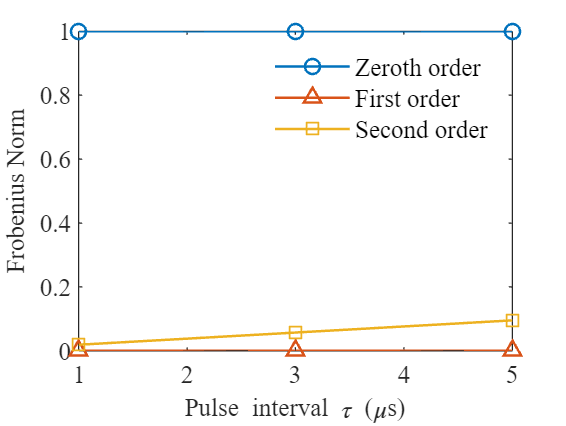

figure()

x=tau_seq*1e6;

norms=Norms_all{3}; %For configuration i, i=1:13

SecondOrderNorm=norms(3,:);
ZerothOrderNorm=norms(1,:);
FirstOrderNorm=norms(2,:);

y1=(ZerothOrderNorm).^0.5;
y2=(FirstOrderNorm).^0.5;
y3=(SecondOrderNorm).^0.5;

plot(x,y1,'-o',x,y2,'-^',x,y3,'-s','LineWidth',1)
xlabel('Pulse interval \tau (\mus)')
ylabel('Frobenius Norm')
legend('Zeroth order','First order','Second order','box','off')
fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")

set(gcf,'unit','centimeters','position',[10,10,8,6]);

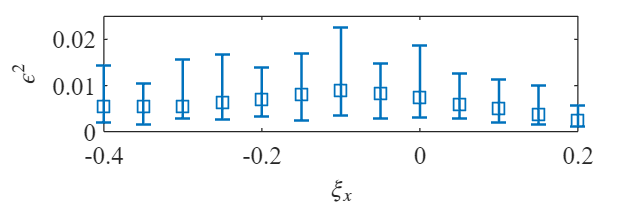

figure()
xi_x_seq=-0.4:0.05:0.2;
x=xi_x_seq;

load Epsilon_N=8_ave100.mat
y3=Epsilon(:,:,3).^2; %Picks the values for tau=5 us

[vari,mean_y]=var(y3,[],2);

max_y=max(y3,[],2);
min_y=min(y3,[],2);
errorbar_neg=mean_y-min_y;
errorbar_pos=max_y-mean_y;

% errorbar_neg=vari.^0.5;
% errorbar_pos=vari.^0.5;

errorbar(x,mean_y,errorbar_neg,errorbar_pos,'s','LineWidth',1)
xlabel('$\xi_x$','interpreter','latex')
ylabel('$\epsilon^2$','interpreter','latex')

ylim([0 0.025])
fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")

set(gcf,'unit','centimeters','position',[10,10,9,3]);

function [norms,cc]=main(nqubit,h,Jij,tau_seq,xi_1,xi_2,xi_3)
[I_single,I_collect]=AngularOperator(nqubit);
X=I_collect{1};
Y=I_collect{2};
Z=I_collect{3};


[H_D,H_tar]=Hamiltonian(nqubit,Jij,xi_1,xi_2,xi_3);

Dz=H_D;
Dx=expm(-1i*pi/2*Y)*Dz*expm(1i*pi/2*Y);
Dy=expm(-1i*pi/2*X)*Dz*expm(1i*pi/2*X);

[H_total,H0,H1,H2,H_total_norm,ZerothOrderNorm,FirstOrderNorm,SecondOrderNorm]=FloquetMagnusExpand(tau_seq,xi_1,xi_2,xi_3);

norms=[ZerothOrderNorm;FirstOrderNorm;SecondOrderNorm;H_total_norm];

find(abs(H0-H_tar)>1e-8)
H0
H_tar


Define the Irreducible Spherical Tensor Operators (ISTO)

[T00_2spin,T10_2spin,...
    T00_a_4spin,T00_b_4spin,T00_c_4spin,...
    T10_a_4spin,T10_b_4spin,T10_c_4spin,T10_d_4spin,T10_e_4spin,T10_f_4spin,...
    T20_a_4spin,T20_b_4spin,T20_c_4spin,T20_d_4spin,T20_e_4spin,T20_f_4spin,...
    T22_a_4spin,T22_b_4spin,T22_c_4spin,T22_d_4spin,T22_e_4spin,T22_f_4spin,...
    T2_2_a_4spin,T2_2_b_4spin,T2_2_c_4spin,T2_2_d_4spin,T2_2_e_4spin,T2_2_f_4spin,...
    T30_a_4spin,T30_b_4spin,T30_c_4spin,...
    T32_a_4spin,T32_b_4spin,T32_c_4spin,...
    T3_2_a_4spin,T3_2_b_4spin,T3_2_c_4spin,...
    T10,T11,T1_1,T20,T21,T2_1,T22,T2_2,T30,T31,T3_1,T32,T3_2,T33,T3_3,T40,T41,T4_1,T42,T4_2,T43,T4_3,T44,T4_4]=IrreducibleSpericalTensor(nqubit);

Decompose the zeroth order of the FM expansion into ISTOs

% [ZeroOrderc10,ZeroOrderc11,ZeroOrderc1_1,...
%     ZeroOrderc20,ZeroOrderc21,ZeroOrderc2_1,ZeroOrderc22,ZeroOrderc2_2,...
%     ZeroOrderc30,ZeroOrderc31,ZeroOrderc3_1,ZeroOrderc32,ZeroOrderc3_2,ZeroOrderc33,ZeroOrderc3_3,...
%     ZeroOrderc40,ZeroOrderc41,ZeroOrderc4_1,ZeroOrderc42,ZeroOrderc4_2,ZeroOrderc43,ZeroOrderc4_3,ZeroOrderc44,ZeroOrderc4_4,...
%     ~,~,~,~,~,~,~,~,~,~]=ISTO_decomposition(H0);
% ZeroOrderc20^0.5
% ZeroOrderc22^0.5
% ZeroOrderc2_2^0.5

Decompose the second order of the FM expansion into ISTOs

[c10,c11,c1_1,...
    c20,c21,c2_1,c22,c2_2,...
    c30,c31,c3_1,c32,c3_2,c33,c3_3,...
    c40,c41,c4_1,c42,c4_2,c43,c4_3,c44,c4_4,...
    c00_2spin,c10_2spin,...
    c00_a_4spin,c00_b_4spin,c00_c_4spin,...
    c10_a_4spin,c10_b_4spin,c10_c_4spin,c10_d_4spin,c10_e_4spin,c10_f_4spin,...
    c20_a_4spin,c20_b_4spin,c20_c_4spin,c20_d_4spin,c20_e_4spin,c20_f_4spin,...
    c22_a_4spin,c22_b_4spin,c22_c_4spin,c22_d_4spin,c22_e_4spin,c22_f_4spin,...
    c2_2_a_4spin,c2_2_b_4spin,c2_2_c_4spin,c2_2_d_4spin,c2_2_e_4spin,c2_2_f_4spin,...
    c30_a_4spin,c30_b_4spin,c30_c_4spin,...
    c32_a_4spin,c32_b_4spin,c32_c_4spin,...
    c3_2_a_4spin,c3_2_b_4spin,c3_2_c_4spin]=ISTO_decomposition(H2);

cc=[c10,c11,c1_1,...
    c20,c21,c2_1,c22,c2_2,...
    c30,c31,c3_1,c32,c3_2,c33,c3_3,...
    c40,c41,c4_1,c42,c4_2,c43,c4_3,c44,c4_4,...
    c00_2spin,c10_2spin,...
    c00_a_4spin,c00_b_4spin,c00_c_4spin,...
    c10_a_4spin,c10_b_4spin,c10_c_4spin,c10_d_4spin,c10_e_4spin,c10_f_4spin,...
    c20_a_4spin,c20_b_4spin,c20_c_4spin,c20_d_4spin,c20_e_4spin,c20_f_4spin,...
    c22_a_4spin,c22_b_4spin,c22_c_4spin,c22_d_4spin,c22_e_4spin,c22_f_4spin,...
    c2_2_a_4spin,c2_2_b_4spin,c2_2_c_4spin,c2_2_d_4spin,c2_2_e_4spin,c2_2_f_4spin,...
    c30_a_4spin,c30_b_4spin,c30_c_4spin,...
    c32_a_4spin,c32_b_4spin,c32_c_4spin,...
    c3_2_a_4spin,c3_2_b_4spin,c3_2_c_4spin];

cc=cc(find(cc>1e-5)); %Extract the non-zero ISTO components
% sum(cc)  %If the sum=1, we are convinced that we have found all the components.

### subfunction [H0,H1,H2]=FloquetMagnusExpand(nqubit,tau_seq,s,xi_1,xi_2,xi_3)

    function [H_total,H0,H1,H2,H_total_norm,ZerothOrderNorm,FirstOrderNorm,SecondOrderNorm]=FloquetMagnusExpand(tau_seq,xi_1,xi_2,xi_3)
        %%% subfunction H_slice(t)
        ZerothOrderNorm=zeros(1,length(tau_seq));
        FirstOrderNorm=zeros(1,length(tau_seq));
        SecondOrderNorm=zeros(1,length(tau_seq));
        % ThirdOrderNorm=zeros(1,length(tau_seq));
        H_total_norm=zeros(1,length(tau_seq));

        for i=1:length(tau_seq)
            tau=tau_seq(i);
            tau_1=tau*(1+xi_3);
            tau_2=tau*(1+xi_2);
            tau_3=tau*(1+xi_1);


In the toggling frame, the time-dependent Hamiltonian during the pulse sequence is a piecewise function

            % t_slice=[tau_1,tau_2,2*tau_3,tau_2,2*tau_1,tau_2,2*tau_3,tau_2,2*tau_1,tau_2,2*tau_3,tau_2,2*tau_1,tau_2,2*tau_3,tau_2,tau_1];
            t_slice=[tau_1,tau_2,2*tau_3,tau_2,2*tau_1,tau_2,2*tau_3,tau_2,tau_1]; %the 8-pulse sequence used in experiment

            t_c=sum(t_slice);

            t_point=zeros(1,length(t_slice));
            for j=1:length(t_slice)
                t_point(j)=sum(t_slice(1:j));
            end

#### Zeroth order

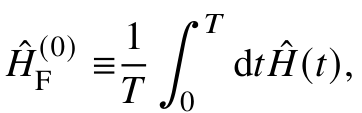

            H0=zeros(2^nqubit);
            for j=1:length(t_slice)
                H0=H0+H_slice(t_point(j))*t_slice(j);
            end
            H0=real(H0/t_c);
            % find(abs(H0-H_tar)>1e-8)
            ZerothOrderNorm(i)=norm(H0,'fro');

#### First order

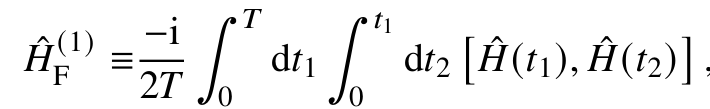

            H1=zeros(2^nqubit);
            for j=2:length(t_slice)
                for k=1:j-1
                    commu=H_slice(t_point(j))*H_slice(t_point(k))-H_slice(t_point(k))*H_slice(t_point(j));
                    H1=H1-1i/2*commu*t_slice(j)*t_slice(k);
                end
            end
            H1=H1/t_c;
            % find(abs(H1)>1e-9);
            FirstOrderNorm(i)=norm(H1,'fro');

#### Second order

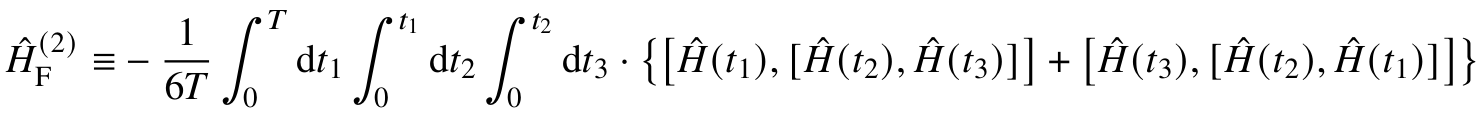

            H2=zeros(2^nqubit);
            for j=2:length(t_slice)
                for k=1:j
                    for l=1:k
                        commu11=H_slice(t_point(k))*H_slice(t_point(l))-H_slice(t_point(l))*H_slice(t_point(k));
                        commu12=H_slice(t_point(j))*commu11-commu11*H_slice(t_point(j));
                        commu21=H_slice(t_point(k))*H_slice(t_point(j))-H_slice(t_point(j))*H_slice(t_point(k));
                        commu22=H_slice(t_point(l))*commu21-commu21*H_slice(t_point(l));
                        commu=commu12+commu22;
                        if k==j
                            H2=H2-1/6*commu*t_slice(j)*t_slice(k)*t_slice(l)/2;
                        elseif l==k
                            H2=H2-1/6*commu*t_slice(j)*t_slice(k)*t_slice(l)/2;
                        else
                            H2=H2-1/6*commu*t_slice(j)*t_slice(k)*t_slice(l);
                        end
                    end
                end
            end
            H2=H2/t_c;
            SecondOrderNorm(i)=norm(H2,'fro');

            H_total=H0+H1+H2;
            H_total_norm(i)=norm(H_total,'fro');
        end
        function H=H_slice(t)
            epsilon=1e-8;
            if t>=0 && t<=tau_1+epsilon
                H=Dz+h*Z;
            elseif t>tau_1 && t<=tau_1+tau_2+epsilon
                H=Dy-h*Y;
            elseif t>tau_1+tau_2 && t<=tau_1+tau_2+2*tau_3+epsilon
                H=Dx+h*X;
            elseif t>tau_1+tau_2+2*tau_3 && t<=tau_1+2*tau_2+2*tau_3+epsilon
                H=Dy+h*Y;
            elseif t>tau_1+2*tau_2+2*tau_3  && t<=3*tau_1+2*tau_2+2*tau_3+epsilon
                H=Dz-h*Z;
            elseif t>3*tau_1+2*tau_2+2*tau_3 && t<=3*tau_1+3*tau_2+2*tau_3+epsilon
                H=Dy-h*Y;
            elseif t>3*tau_1+3*tau_2+2*tau_3 && t<=3*tau_1+3*tau_2+4*tau_3+epsilon
                H=Dx-h*X;
            elseif t>3*tau_1+3*tau_2+4*tau_3 && t<=3*tau_1+4*tau_2+4*tau_3+epsilon
                H=Dy+h*Y;
            elseif t>3*tau_1+4*tau_2+4*tau_3 && t<=5*tau_1+4*tau_2+4*tau_3+epsilon
                H=Dz+h*Z;
                % elseif t>5*tau_1+4*tau_2+4*tau_3 && t<=5*tau_1+5*tau_2+4*tau_3+epsilon
                %     H=Dy+h*Y;
                % elseif t>5*tau_1+5*tau_2+4*tau_3 && t<=5*tau_1+5*tau_2+6*tau_3+epsilon
                %     H=Dx-h*X;
                % elseif t>5*tau_1+5*tau_2+6*tau_3 && t<=5*tau_1+6*tau_2+6*tau_3+epsilon
                %     H=Dy-h*Y;
                % elseif t>5*tau_1+6*tau_2+6*tau_3 && t<=7*tau_1+6*tau_2+6*tau_3+epsilon
                %     H=Dz-h*Z;
                % elseif t>7*tau_1+6*tau_2+6*tau_3 && t<=7*tau_1+7*tau_2+6*tau_3+epsilon
                %     H=Dy+h*Y;
                % elseif t>7*tau_1+7*tau_2+6*tau_3 && t<=7*tau_1+7*tau_2+8*tau_3+epsilon
                %     H=Dx+h*X;
                % elseif t>7*tau_1+7*tau_2+8*tau_3 && t<=7*tau_1+8*tau_2+8*tau_3+epsilon
                %     H=Dy-h*Y;
                % elseif t>7*tau_1+8*tau_2+8*tau_3 && t<=8*tau_1+8*tau_2+8*tau_3+epsilon
                %     H=Dz+h*Z;
            end
        end
    end

### subfunction [T10,T11,T1_1,T20,T21,T2_1,T22,T2_2]=IrreducibleSpericalTensor(nqubit)


$$T_{1,0}^j=\sigma_{z}^j$$



$$T_{1,1}^j=-\frac{1}{\sqrt{2}}\left(\sigma_x^j+i \sigma_y^j\right)=-\sigma_+^j$$



$$T_{1,-1}^j=\frac{1}{\sqrt{2}}\left(\sigma_x^j-i \sigma_y^j\right)=\sigma_-^j$$



$$T_{2,0}^{(j,k)}=\frac{1}{\sqrt{6}}\left(2 \sigma_z^j \sigma_z^k-\sigma_x^j \sigma_x^k-\sigma_y^j \sigma_y^k\right)$$



$$T_{2,1}^{(j,k)}=-\frac{1}{\sqrt{2}}\left(\sigma_z^j \sigma_{+}^k+\sigma_{+}^j \sigma_z^k\right)$$



$$T_{2,-1}^{(j,k)}=\frac{1}{\sqrt{2}}\left(\sigma_z^j \sigma_{-}^k+\sigma_{-}^j \sigma_z^k\right)$$



$$T_{2,2}^{(j,k)}=\sigma_{+}^j \sigma_{+}^k$$



$$T_{2,-2}^{(j,k)}=\sigma_{-}^j \sigma_{-}^k$$



$$\cdots$$


    function [T00_2spin,T10_2spin,...
            T00_a_4spin,T00_b_4spin,T00_c_4spin,...
            T10_a_4spin,T10_b_4spin,T10_c_4spin,T10_d_4spin,T10_e_4spin,T10_f_4spin,...
            T20_a_4spin,T20_b_4spin,T20_c_4spin,T20_d_4spin,T20_e_4spin,T20_f_4spin,...
            T22_a_4spin,T22_b_4spin,T22_c_4spin,T22_d_4spin,T22_e_4spin,T22_f_4spin,...
            T2_2_a_4spin,T2_2_b_4spin,T2_2_c_4spin,T2_2_d_4spin,T2_2_e_4spin,T2_2_f_4spin,...
            T30_a_4spin,T30_b_4spin,T30_c_4spin,...
            T32_a_4spin,T32_b_4spin,T32_c_4spin,...
            T3_2_a_4spin,T3_2_b_4spin,T3_2_c_4spin,...
            T10,T11,T1_1,T20,T21,T2_1,T22,T2_2,T30,T31,T3_1,T32,T3_2,T33,T3_3,T40,T41,T4_1,T42,T4_2,T43,T4_3,T44,T4_4]=IrreducibleSpericalTensor(nqubit)


### 0-spin tensor is the Identity matrix, Rank=0, Order=0

### 1-Spin tensors, Rank=1

        T10=cell(1,nqubit);
        T11=cell(1,nqubit);
        T1_1=cell(1,nqubit);

        for i=1:nqubit
            T10{i}=2*I_single{3,i};
            T11{i}=-2^0.5*(I_single{1,i}+1i*I_single{2,i});
            T1_1{i}=2^0.5*(I_single{1,i}-1i*I_single{2,i});
        end

### 2-spin tensors, Rank=2,1,0

        T00_2spin=cell(nqubit,nqubit);

        T10_2spin=cell(nqubit,nqubit);
        T11_2spin=cell(nqubit,nqubit);
        T1_1_2spin=cell(nqubit,nqubit);

        T20=cell(nqubit,nqubit);
        T21=cell(nqubit,nqubit);
        T2_1=cell(nqubit,nqubit);
        T22=cell(nqubit,nqubit);
        T2_2=cell(nqubit,nqubit);
        for i=1:nqubit
            for j=i+1:nqubit

   Rank=0   

                T00_2spin{i,j}=ClebschGordan(1,1,0,0,0,0)*T10{i}*T10{j}+ClebschGordan(1,1,0,1,-1,0)*T11{i}*T1_1{j}+ClebschGordan(1,1,0,-1,1,0)*T1_1{i}*T11{j};

   Rank=1  

                T10_2spin{i,j}=ClebschGordan(1,1,1,0,0,0)*T10{i}*T10{j}+ClebschGordan(1,1,1,1,-1,0)*T11{i}*T1_1{j}+ClebschGordan(1,1,1,-1,1,0)*T1_1{i}*T11{j};
                T11_2spin{i,j}=ClebschGordan(1,1,1,0,1,1)*T10{i}*T11{j}+ClebschGordan(1,1,1,1,0,1)*T11{i}*T10{j};
                T1_1_2spin{i,j}=ClebschGordan(1,1,1,0,-1,-1)*T10{i}*T1_1{j}+ClebschGordan(1,1,1,-1,0,-1)*T1_1{i}*T10{j};

  Rank=2  

                T20{i,j}=ClebschGordan(1,1,2,0,0,0)*T10{i}*T10{j}+ClebschGordan(1,1,2,1,-1,0)*T11{i}*T1_1{j}+ClebschGordan(1,1,2,-1,1,0)*T1_1{i}*T11{j};
                T21{i,j}=ClebschGordan(1,1,2,1,0,1)*T11{i}*T10{j}+ClebschGordan(1,1,2,0,1,1)*T10{i}*T11{j};
                T2_1{i,j}=ClebschGordan(1,1,2,-1,0,-1)*T1_1{i}*T10{j}+ClebschGordan(1,1,2,0,-1,-1)*T10{i}*T1_1{j};
                T22{i,j}=ClebschGordan(1,1,2,1,1,2)*T11{i}*T11{j};
                T2_2{i,j}=ClebschGordan(1,1,2,-1,-1,-2)*T1_1{i}*T1_1{j};
            end
        end

### 3-spin tensors, Rank=3,2,1,0

        T30=cell(nqubit,nqubit,nqubit);
        T31=cell(nqubit,nqubit,nqubit);
        T3_1=cell(nqubit,nqubit,nqubit);
        T32=cell(nqubit,nqubit,nqubit);
        T3_2=cell(nqubit,nqubit,nqubit);
        T33=cell(nqubit,nqubit,nqubit);
        T3_3=cell(nqubit,nqubit,nqubit);
        for i=1:nqubit
            for j=i+1:nqubit
                for k=j+1:nqubit
                    T30{i,j,k}=ClebschGordan(2,1,3,0,0,0)*T20{i,j}*T10{k}+ClebschGordan(2,1,3,1,-1,0)*T21{i,j}*T1_1{k}+ClebschGordan(2,1,3,-1,1,0)*T2_1{i,j}*T11{k};
                    T31{i,j,k}=ClebschGordan(2,1,3,1,0,1)*T21{i,j}*T10{k}+ClebschGordan(2,1,3,0,1,1)*T20{i,j}*T11{k}+ClebschGordan(2,1,3,2,-1,1)*T22{i,j}*T1_1{k};
                    T3_1{i,j,k}=ClebschGordan(2,1,3,-1,0,-1)*T2_1{i,j}*T10{k}+ClebschGordan(2,1,3,0,-1,-1)*T20{i,j}*T1_1{k}+ClebschGordan(2,1,3,-2,1,-1)*T2_2{i,j}*T11{k};
                    T32{i,j,k}=ClebschGordan(2,1,3,1,1,2)*T21{i,j}*T11{k}+ClebschGordan(2,1,3,2,0,2)*T22{i,j}*T10{k};
                    T3_2{i,j,k}=ClebschGordan(2,1,3,-1,-1,-2)*T2_1{i,j}*T1_1{k}+ClebschGordan(2,1,3,-2,0,-2)*T2_2{i,j}*T10{k};
                    T33{i,j,k}=ClebschGordan(2,1,3,2,1,3)*T22{i,j}*T11{k};
                    T3_3{i,j,k}=ClebschGordan(2,1,3,-2,-1,-3)*T2_2{i,j}*T1_1{k};
                end
            end
        end

### 4 spin tensors, Rank=4,3,2,1,0

        T00_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T00_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T00_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);

        T20_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T20_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T20_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T20_d_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T20_e_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T20_f_4spin=cell(nqubit,nqubit,nqubit,nqubit);

        T22_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T22_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T22_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T22_d_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T22_e_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T22_f_4spin=cell(nqubit,nqubit,nqubit,nqubit);

        T2_2_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T2_2_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T2_2_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T2_2_d_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T2_2_e_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T2_2_f_4spin=cell(nqubit,nqubit,nqubit,nqubit);


        T10_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T10_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T10_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T10_d_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T10_e_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T10_f_4spin=cell(nqubit,nqubit,nqubit,nqubit);

        T30_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T30_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T30_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);


        T32_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T32_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T32_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);


        T3_2_a_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T3_2_b_4spin=cell(nqubit,nqubit,nqubit,nqubit);
        T3_2_c_4spin=cell(nqubit,nqubit,nqubit,nqubit);


        T40=cell(nqubit,nqubit,nqubit,nqubit);
        T41=cell(nqubit,nqubit,nqubit,nqubit);
        T4_1=cell(nqubit,nqubit,nqubit,nqubit);
        T42=cell(nqubit,nqubit,nqubit,nqubit);
        T4_2=cell(nqubit,nqubit,nqubit,nqubit);
        T43=cell(nqubit,nqubit,nqubit,nqubit);
        T4_3=cell(nqubit,nqubit,nqubit,nqubit);
        T44=cell(nqubit,nqubit,nqubit,nqubit);
        T4_4=cell(nqubit,nqubit,nqubit,nqubit);


        for i=1:nqubit
            for j=i+1:nqubit
                for k=j+1:nqubit
                    for l=k+1:nqubit

  Rank=0

                        T00_a_4spin{i,j,k,l}=ClebschGordan(2,2,0,0,0,0)*T20{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,0,1,-1,0)*T21{i,j}*T2_1{k,l}+ClebschGordan(2,2,0,-1,1,0)*T2_1{i,j}*T21{k,l}...
                            +ClebschGordan(2,2,0,-2,2,0)*T2_2{i,j}*T22{k,l}+ClebschGordan(2,2,0,2,-2,0)*T22{i,j}*T2_2{k,l};

                        T00_b_4spin{i,j,k,l}=ClebschGordan(1,1,0,0,0,0)*T10_2spin{i,j}*T10_2spin{k,l}...
                            +ClebschGordan(1,1,0,1,-1,0)*T11_2spin{i,j}*T1_1_2spin{k,l}+ClebschGordan(1,1,0,-1,1,0)*T1_1_2spin{i,j}*T11_2spin{k,l};


                        T00_c_4spin{i,j,k,l}=ClebschGordan(0,0,0,0,0,0)*T00_2spin{i,j}*T00_2spin{k,l};
                        % trace(T00_4spin{i,j,k,l}*T00_4spin{i,j,k,l}')

  Rank=1

                        T10_a_4spin{i,j,k,l}=ClebschGordan(2,2,1,0,0,0)*T20{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,1,1,-1,0)*T21{i,j}*T2_1{k,l}+ClebschGordan(2,2,1,-1,1,0)*T2_1{i,j}*T21{k,l}...
                            +ClebschGordan(2,2,1,-2,2,0)*T2_2{i,j}*T22{k,l}+ClebschGordan(2,2,1,2,-2,0)*T22{i,j}*T2_2{k,l};

                        T10_b_4spin{i,j,k,l}=ClebschGordan(2,1,1,1,-1,0)*T21{i,j}*T1_1_2spin{k,l}+ClebschGordan(2,1,1,-1,1,0)*T2_1{i,j}*T11_2spin{k,l}...
                            +ClebschGordan(2,1,1,0,0,0)*T20{i,j}*T10_2spin{k,l};

                        T10_c_4spin{i,j,k,l}=ClebschGordan(1,2,1,1,-1,0)*T11_2spin{i,j}*T2_1{k,l}+ClebschGordan(1,2,1,-1,1,0)*T1_1_2spin{i,j}*T21{k,l}...
                            +ClebschGordan(1,2,1,0,0,0)*T10_2spin{i,j}*T20{k,l};

                        T10_d_4spin{i,j,k,l}=ClebschGordan(1,1,1,0,0,0)*T10_2spin{i,j}*T10_2spin{k,l}...
                            +ClebschGordan(1,1,1,1,-1,0)*T11_2spin{i,j}*T1_1_2spin{k,l}+ClebschGordan(1,1,1,-1,1,0)*T1_1_2spin{i,j}*T11_2spin{k,l};

                        T10_e_4spin{i,j,k,l}=ClebschGordan(1,0,1,0,0,0)*T10_2spin{i,j}*T00_2spin{k,l};

                        T10_f_4spin{i,j,k,l}=ClebschGordan(0,1,1,0,0,0)*T00_2spin{i,j}*T10_2spin{k,l};

                        % trace(T10_a_4spin{i,j,k,l}*T10_b_4spin{i,j,k,l})


  Rank=2

                        T20_a_4spin{i,j,k,l}=ClebschGordan(2,2,2,0,0,0)*T20{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,2,1,-1,0)*T21{i,j}*T2_1{k,l}+ClebschGordan(2,2,2,-1,1,0)*T2_1{i,j}*T21{k,l}...
                            +ClebschGordan(2,2,2,-2,2,0)*T2_2{i,j}*T22{k,l}+ClebschGordan(2,2,2,2,-2,0)*T22{i,j}*T2_2{k,l};

                        T20_b_4spin{i,j,k,l}=ClebschGordan(2,1,2,1,-1,0)*T21{i,j}*T1_1_2spin{k,l}+ClebschGordan(2,1,2,-1,1,0)*T2_1{i,j}*T11_2spin{k,l}...
                            +ClebschGordan(2,1,2,0,0,0)*T20{i,j}*T10_2spin{k,l};

                        T20_c_4spin{i,j,k,l}=ClebschGordan(1,2,2,1,-1,0)*T11_2spin{i,j}*T2_1{k,l}+ClebschGordan(1,2,2,-1,1,0)*T1_1_2spin{i,j}*T21{k,l}...
                            +ClebschGordan(1,2,2,0,0,0)*T10_2spin{i,j}*T20{k,l};

                        T20_d_4spin{i,j,k,l}=ClebschGordan(1,1,2,0,0,0)*T10_2spin{i,j}*T10_2spin{k,l}...
                            +ClebschGordan(1,1,2,1,-1,0)*T11_2spin{i,j}*T1_1_2spin{k,l}+ClebschGordan(1,1,2,-1,1,0)*T1_1_2spin{i,j}*T11_2spin{k,l};

                        T20_e_4spin{i,j,k,l}=ClebschGordan(2,0,2,0,0,0)*T20{i,j}*T00_2spin{k,l};

                        T20_f_4spin{i,j,k,l}=ClebschGordan(0,2,2,0,0,0)*T00_2spin{i,j}*T20{k,l};

                        % trace(T20_4spin{i,j,k,l}*T20_4spin{i,j,k,l}')

                        T22_a_4spin{i,j,k,l}=ClebschGordan(2,2,2,2,0,2)*T22{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,2,0,2,2)*T20{i,j}*T22{k,l}+ClebschGordan(2,2,2,1,1,2)*T21{i,j}*T21{k,l};

                        T22_b_4spin{i,j,k,l}=ClebschGordan(2,1,2,2,0,2)*T22{i,j}*T10_2spin{k,l}+ClebschGordan(2,1,2,1,1,2)*T21{i,j}*T11_2spin{k,l};

                        T22_c_4spin{i,j,k,l}=ClebschGordan(1,2,2,0,2,2)*T10_2spin{i,j}*T22{k,l}+ClebschGordan(1,2,2,1,1,2)*T11_2spin{i,j}*T21{k,l};

                        T22_d_4spin{i,j,k,l}=ClebschGordan(1,1,2,1,1,2)*T11_2spin{i,j}*T11_2spin{k,l};

                        T22_e_4spin{i,j,k,l}=ClebschGordan(2,0,2,2,0,2)*T22{i,j}*T00_2spin{k,l};

                        T22_f_4spin{i,j,k,l}=ClebschGordan(0,2,2,0,2,2)*T00_2spin{i,j}*T22{k,l};


                        % trace(T22_4spin{i,j,k,l}*T22_4spin{i,j,k,l}')

                        T2_2_a_4spin{i,j,k,l}=ClebschGordan(2,2,2,-2,0,-2)*T2_2{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,2,0,-2,-2)*T20{i,j}*T2_2{k,l}+ClebschGordan(2,2,2,-1,-1,-2)*T2_1{i,j}*T2_1{k,l};

                        T2_2_b_4spin{i,j,k,l}=ClebschGordan(2,1,2,-2,0,-2)*T2_2{i,j}*T10_2spin{k,l}+ClebschGordan(2,1,2,-1,-1,-2)*T2_1{i,j}*T1_1_2spin{k,l};

                        T2_2_c_4spin{i,j,k,l}=ClebschGordan(1,2,2,0,-2,-2)*T10_2spin{i,j}*T2_2{k,l}+ClebschGordan(1,2,2,-1,-1,-2)*T1_1_2spin{i,j}*T2_1{k,l};

                        T2_2_d_4spin{i,j,k,l}=ClebschGordan(1,1,2,-1,-1,-2)*T1_1_2spin{i,j}*T1_1_2spin{k,l};

                        T2_2_e_4spin{i,j,k,l}=ClebschGordan(2,0,2,-2,0,-2)*T2_2{i,j}*T00_2spin{k,l};

                        T2_2_f_4spin{i,j,k,l}=ClebschGordan(0,2,2,0,-2,-2)*T00_2spin{i,j}*T2_2{k,l};


                        % trace(T2_2_4spin{i,j,k,l}*T2_2_4spin{i,j,k,l}')
                        %

  Rank=3

                        T30_a_4spin{i,j,k,l}=ClebschGordan(2,2,3,0,0,0)*T20{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,3,1,-1,0)*T21{i,j}*T2_1{k,l}+ClebschGordan(2,2,3,-1,1,0)*T2_1{i,j}*T21{k,l}...
                            +ClebschGordan(2,2,3,-2,2,0)*T2_2{i,j}*T22{k,l}+ClebschGordan(2,2,3,2,-2,0)*T22{i,j}*T2_2{k,l};

                        T30_b_4spin{i,j,k,l}=ClebschGordan(2,1,3,1,-1,0)*T21{i,j}*T1_1_2spin{k,l}+ClebschGordan(2,1,3,-1,1,0)*T2_1{i,j}*T11_2spin{k,l}...
                            +ClebschGordan(2,1,3,0,0,0)*T20{i,j}*T10_2spin{k,l};

                        T30_c_4spin{i,j,k,l}=ClebschGordan(1,2,3,1,-1,0)*T11_2spin{i,j}*T2_1{k,l}+ClebschGordan(1,2,3,-1,1,0)*T1_1_2spin{i,j}*T21{k,l}...
                            +ClebschGordan(1,2,3,0,0,0)*T10_2spin{i,j}*T20{k,l};

                        % trace(T30_a_4spin{i,j,k,l}*T30_a_4spin{i,j,k,l})


                        T32_a_4spin{i,j,k,l}=ClebschGordan(2,2,3,2,0,2)*T22{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,3,0,2,2)*T20{i,j}*T22{k,l}+ClebschGordan(2,2,3,1,1,2)*T21{i,j}*T21{k,l};

                        T32_b_4spin{i,j,k,l}=ClebschGordan(2,1,3,2,0,2)*T22{i,j}*T10_2spin{k,l}+ClebschGordan(2,1,3,1,1,2)*T21{i,j}*T11_2spin{k,l};

                        T32_c_4spin{i,j,k,l}=ClebschGordan(1,2,3,0,2,2)*T10_2spin{i,j}*T22{k,l}+ClebschGordan(1,2,3,1,1,2)*T11_2spin{i,j}*T21{k,l};
                        % trace(T32_4spin{i,j,k,l}*T32_4spin{i,j,k,l}')

                        T3_2_a_4spin{i,j,k,l}=ClebschGordan(2,2,3,-2,0,-2)*T2_2{i,j}*T20{k,l}...
                            +ClebschGordan(2,2,3,0,-2,-2)*T20{i,j}*T2_2{k,l}+ClebschGordan(2,2,3,-1,-1,-2)*T2_1{i,j}*T2_1{k,l};

                        T3_2_b_4spin{i,j,k,l}=ClebschGordan(2,1,3,-2,0,-2)*T2_2{i,j}*T10_2spin{k,l}+ClebschGordan(2,1,3,-1,-1,-2)*T2_1{i,j}*T1_1_2spin{k,l};

                        T3_2_c_4spin{i,j,k,l}=ClebschGordan(1,2,3,0,-2,-2)*T10_2spin{i,j}*T2_2{k,l}+ClebschGordan(1,2,3,-1,-1,-2)*T1_1_2spin{i,j}*T2_1{k,l};
                        %

  Rank=4

                        T40{i,j,k,l}=ClebschGordan(3,1,4,0,0,0)*T30{i,j,k}*T10{l}+ClebschGordan(3,1,4,1,-1,0)*T31{i,j,k}*T1_1{l}+ClebschGordan(3,1,4,-1,1,0)*T3_1{i,j,k}*T11{l};

                        T41{i,j,k,l}=ClebschGordan(3,1,4,1,0,1)*T31{i,j,k}*T10{l}+ClebschGordan(3,1,4,0,1,1)*T30{i,j,k}*T11{l}+ClebschGordan(3,1,4,2,-1,1)*T32{i,j,k}*T1_1{l};

                        T4_1{i,j,k,l}=ClebschGordan(3,1,4,-1,0,-1)*T3_1{i,j,k}*T10{l}+ClebschGordan(3,1,4,0,-1,-1)*T30{i,j,k}*T1_1{l}+ClebschGordan(3,1,4,-2,1,-1)*T3_2{i,j,k}*T11{l};

                        T42{i,j,k,l}=ClebschGordan(3,1,4,2,0,2)*T32{i,j,k}*T10{l}+ClebschGordan(3,1,4,1,1,2)*T31{i,j,k}*T11{l}+ClebschGordan(3,1,4,3,-1,2)*T33{i,j,k}*T1_1{l};

                        T4_2{i,j,k,l}=ClebschGordan(3,1,4,-2,0,-2)*T3_2{i,j,k}*T10{l}+ClebschGordan(3,1,4,-1,-1,-2)*T3_1{i,j,k}*T1_1{l}+ClebschGordan(3,1,4,-3,1,-2)*T3_3{i,j,k}*T11{l};

                        T43{i,j,k,l}=ClebschGordan(3,1,4,2,1,3)*T32{i,j,k}*T11{l}+ClebschGordan(3,1,4,3,0,3)*T33{i,j,k}*T10{l};

                        T4_3{i,j,k,l}=ClebschGordan(3,1,4,-2,-1,-3)*T3_2{i,j,k}*T1_1{l}+ClebschGordan(3,1,4,-3,0,-3)*T3_3{i,j,k}*T10{l};

                        T44{i,j,k,l}=ClebschGordan(3,1,4,3,1,4)*T33{i,j,k}*T11{l};

                        T4_4{i,j,k,l}=ClebschGordan(3,1,4,-3,-1,-4)*T3_3{i,j,k}*T1_1{l};
                    end
                end
            end
        end
    end

### subfunction [c10,c11,c1_1,c20,c21,c2_1,c22,c2_2]=ISTO_decomposion(nqubit,H,T10,T11,T1_1,T20,T21,T2_1,T22,T2_2)

    function [c10,c11,c1_1,...
            c20,c21,c2_1,c22,c2_2,...
            c30,c31,c3_1,c32,c3_2,c33,c3_3,...
            c40,c41,c4_1,c42,c4_2,c43,c4_3,c44,c4_4,...
            c00_2spin,c10_2spin,...
            c00_a_4spin,c00_b_4spin,c00_c_4spin,...
            c10_a_4spin,c10_b_4spin,c10_c_4spin,c10_d_4spin,c10_e_4spin,c10_f_4spin,...
            c20_a_4spin,c20_b_4spin,c20_c_4spin,c20_d_4spin,c20_e_4spin,c20_f_4spin,...
            c22_a_4spin,c22_b_4spin,c22_c_4spin,c22_d_4spin,c22_e_4spin,c22_f_4spin,...
            c2_2_a_4spin,c2_2_b_4spin,c2_2_c_4spin,c2_2_d_4spin,c2_2_e_4spin,c2_2_f_4spin,...
            c30_a_4spin,c30_b_4spin,c30_c_4spin,...
            c32_a_4spin,c32_b_4spin,c32_c_4spin,...
            c3_2_a_4spin,c3_2_b_4spin,c3_2_c_4spin]=ISTO_decomposition(H)

        A10=zeros(1,nqubit);
        A11=zeros(1,nqubit);
        A1_1=zeros(1,nqubit);
        A20=zeros(1,nqubit*(nqubit-1)/2);
        A21=zeros(1,nqubit*(nqubit-1)/2);
        A2_1=zeros(1,nqubit*(nqubit-1)/2);
        A22=zeros(1,nqubit*(nqubit-1)/2);
        A2_2=zeros(1,nqubit*(nqubit-1)/2);

        A30=zeros(1,nchoosek(nqubit,3));
        A31=zeros(1,nchoosek(nqubit,3));
        A3_1=zeros(1,nchoosek(nqubit,3));
        A32=zeros(1,nchoosek(nqubit,3));
        A3_2=zeros(1,nchoosek(nqubit,3));
        A33=zeros(1,nchoosek(nqubit,3));
        A3_3=zeros(1,nchoosek(nqubit,3));

        A40=zeros(1,nchoosek(nqubit,4));
        A41=zeros(1,nchoosek(nqubit,4));
        A4_1=zeros(1,nchoosek(nqubit,4));
        A42=zeros(1,nchoosek(nqubit,4));
        A4_2=zeros(1,nchoosek(nqubit,4));
        A43=zeros(1,nchoosek(nqubit,4));
        A4_3=zeros(1,nchoosek(nqubit,4));
        A44=zeros(1,nchoosek(nqubit,4));
        A4_4=zeros(1,nchoosek(nqubit,4));

        A00_2spin=zeros(1,nchoosek(nqubit,2));
        A10_2spin=zeros(1,nchoosek(nqubit,2));

        A00_a_4spin=zeros(1,nchoosek(nqubit,4));
        A00_b_4spin=zeros(1,nchoosek(nqubit,4));
        A00_c_4spin=zeros(1,nchoosek(nqubit,4));

        A10_a_4spin=zeros(1,nchoosek(nqubit,4));
        A10_b_4spin=zeros(1,nchoosek(nqubit,4));
        A10_c_4spin=zeros(1,nchoosek(nqubit,4));
        A10_d_4spin=zeros(1,nchoosek(nqubit,4));
        A10_e_4spin=zeros(1,nchoosek(nqubit,4));
        A10_f_4spin=zeros(1,nchoosek(nqubit,4));

        A20_a_4spin=zeros(1,nchoosek(nqubit,4));
        A20_b_4spin=zeros(1,nchoosek(nqubit,4));
        A20_c_4spin=zeros(1,nchoosek(nqubit,4));
        A20_d_4spin=zeros(1,nchoosek(nqubit,4));
        A20_e_4spin=zeros(1,nchoosek(nqubit,4));
        A20_f_4spin=zeros(1,nchoosek(nqubit,4));

        A22_a_4spin=zeros(1,nchoosek(nqubit,4));
        A22_b_4spin=zeros(1,nchoosek(nqubit,4));
        A22_c_4spin=zeros(1,nchoosek(nqubit,4));
        A22_d_4spin=zeros(1,nchoosek(nqubit,4));
        A22_e_4spin=zeros(1,nchoosek(nqubit,4));
        A22_f_4spin=zeros(1,nchoosek(nqubit,4));

        A2_2_a_4spin=zeros(1,nchoosek(nqubit,4));
        A2_2_b_4spin=zeros(1,nchoosek(nqubit,4));
        A2_2_c_4spin=zeros(1,nchoosek(nqubit,4));
        A2_2_d_4spin=zeros(1,nchoosek(nqubit,4));
        A2_2_e_4spin=zeros(1,nchoosek(nqubit,4));
        A2_2_f_4spin=zeros(1,nchoosek(nqubit,4));


        A30_a_4spin=zeros(1,nchoosek(nqubit,4));
        A30_b_4spin=zeros(1,nchoosek(nqubit,4));
        A30_c_4spin=zeros(1,nchoosek(nqubit,4));


        A32_a_4spin=zeros(1,nchoosek(nqubit,4));
        A32_b_4spin=zeros(1,nchoosek(nqubit,4));
        A32_c_4spin=zeros(1,nchoosek(nqubit,4));


        A3_2_a_4spin=zeros(1,nchoosek(nqubit,4));
        A3_2_b_4spin=zeros(1,nchoosek(nqubit,4));
        A3_2_c_4spin=zeros(1,nchoosek(nqubit,4));

        a=1;
        b=1;
        c=1;
        for i=1:nqubit
            A10(i)=trace(T10{i}'*H);
            A11(i)=trace(T11{i}'*H);
            A1_1(i)=trace(T1_1{i}'*H);
            for j=i+1:nqubit
                A20(a)=trace(T20{i,j}'*H);
                A21(a)=trace(T21{i,j}'*H);
                A2_1(a)=trace(T2_1{i,j}'*H);
                A22(a)=trace(T22{i,j}'*H);
                A2_2(a)=trace(T2_2{i,j}'*H);
                A00_2spin(a)=trace(T00_2spin{i,j}'*H);
                A10_2spin(a)=trace(T10_2spin{i,j}'*H);
                a=a+1;
                for k=j+1:nqubit
                    A30(b)=trace(T30{i,j,k}'*H);
                    A31(b)=trace(T31{i,j,k}'*H);
                    A3_1(b)=trace(T3_1{i,j,k}'*H);
                    A32(b)=trace(T32{i,j,k}'*H);
                    A3_2(b)=trace(T3_2{i,j,k}'*H);
                    A33(b)=trace(T33{i,j,k}'*H);
                    A3_3(b)=trace(T3_3{i,j,k}'*H);
                    b=b+1;
                    for l=k+1:nqubit
                        A40(c)=trace(T40{i,j,k,l}'*H);
                        A41(c)=trace(T41{i,j,k,l}'*H);
                        A4_1(c)=trace(T4_1{i,j,k,l}'*H);
                        A42(c)=trace(T42{i,j,k,l}'*H);
                        A4_2(c)=trace(T4_2{i,j,k,l}'*H);
                        A43(c)=trace(T43{i,j,k,l}'*H);
                        A4_3(c)=trace(T4_3{i,j,k,l}'*H);
                        A44(c)=trace(T44{i,j,k,l}'*H);
                        A4_4(c)=trace(T4_4{i,j,k,l}'*H);

                        A00_a_4spin(c)=trace(T00_a_4spin{i,j,k,l}'*H);
                        A00_b_4spin(c)=trace(T00_b_4spin{i,j,k,l}'*H);
                        A00_c_4spin(c)=trace(T00_c_4spin{i,j,k,l}'*H);

                        A10_a_4spin(c)=trace(T10_a_4spin{i,j,k,l}'*H);
                        A10_b_4spin(c)=trace(T10_b_4spin{i,j,k,l}'*H);
                        A10_c_4spin(c)=trace(T10_c_4spin{i,j,k,l}'*H);
                        A10_d_4spin(c)=trace(T10_d_4spin{i,j,k,l}'*H);
                        A10_e_4spin(c)=trace(T10_e_4spin{i,j,k,l}'*H);
                        A10_f_4spin(c)=trace(T10_f_4spin{i,j,k,l}'*H);

                        A20_a_4spin(c)=trace(T20_a_4spin{i,j,k,l}'*H);
                        A20_b_4spin(c)=trace(T20_b_4spin{i,j,k,l}'*H);
                        A20_c_4spin(c)=trace(T20_c_4spin{i,j,k,l}'*H);
                        A20_d_4spin(c)=trace(T20_d_4spin{i,j,k,l}'*H);
                        A20_e_4spin(c)=trace(T20_e_4spin{i,j,k,l}'*H);
                        A20_f_4spin(c)=trace(T20_f_4spin{i,j,k,l}'*H);

                        A22_a_4spin(c)=trace(T22_a_4spin{i,j,k,l}'*H);
                        A22_b_4spin(c)=trace(T22_b_4spin{i,j,k,l}'*H);
                        A22_c_4spin(c)=trace(T22_c_4spin{i,j,k,l}'*H);
                        A22_d_4spin(c)=trace(T22_d_4spin{i,j,k,l}'*H);
                        A22_e_4spin(c)=trace(T22_e_4spin{i,j,k,l}'*H);
                        A22_f_4spin(c)=trace(T22_f_4spin{i,j,k,l}'*H);

                        A2_2_a_4spin(c)=trace(T2_2_a_4spin{i,j,k,l}'*H);
                        A2_2_b_4spin(c)=trace(T2_2_b_4spin{i,j,k,l}'*H);
                        A2_2_c_4spin(c)=trace(T2_2_c_4spin{i,j,k,l}'*H);
                        A2_2_d_4spin(c)=trace(T2_2_d_4spin{i,j,k,l}'*H);
                        A2_2_e_4spin(c)=trace(T2_2_e_4spin{i,j,k,l}'*H);
                        A2_2_f_4spin(c)=trace(T2_2_f_4spin{i,j,k,l}'*H);

                        A30_a_4spin(c)=trace(T30_a_4spin{i,j,k,l}'*H);
                        A30_b_4spin(c)=trace(T30_b_4spin{i,j,k,l}'*H);
                        A30_c_4spin(c)=trace(T30_c_4spin{i,j,k,l}'*H);

                        A32_a_4spin(c)=trace(T32_a_4spin{i,j,k,l}'*H);
                        A32_b_4spin(c)=trace(T32_b_4spin{i,j,k,l}'*H);
                        A32_c_4spin(c)=trace(T32_c_4spin{i,j,k,l}'*H);

                        A3_2_a_4spin(c)=trace(T3_2_a_4spin{i,j,k,l}'*H);
                        A3_2_b_4spin(c)=trace(T3_2_b_4spin{i,j,k,l}'*H);
                        A3_2_c_4spin(c)=trace(T3_2_c_4spin{i,j,k,l}'*H);

                        c=c+1;
                    end
                end
            end
        end
        Normsquared=trace(H*H');
        c10=A10*A10'/Normsquared/2^nqubit;
        c11=A11*A11'/Normsquared/2^nqubit;
        c1_1=A1_1*A1_1'/Normsquared/2^nqubit;
        c20=A20*A20'/Normsquared/2^nqubit;
        c21=A21*A21'/Normsquared/2^nqubit;
        c2_1=A2_1*A2_1'/Normsquared/2^nqubit;
        c22=A22*A22'/Normsquared/2^nqubit;
        c2_2=A2_2*A2_2'/Normsquared/2^nqubit;

        c30=A30*A30'/Normsquared/2^nqubit;
        c31=A31*A31'/Normsquared/2^nqubit;
        c3_1=A3_1*A3_1'/Normsquared/2^nqubit;
        c32=A32*A32'/Normsquared/2^nqubit;
        c3_2=A3_2*A3_2'/Normsquared/2^nqubit;
        c33=A33*A33'/Normsquared/2^nqubit;
        c3_3=A3_3*A3_3'/Normsquared/2^nqubit;

        c40=A40*A40'/Normsquared/2^nqubit;
        c41=A41*A41'/Normsquared/2^nqubit;
        c4_1=A4_1*A4_1'/Normsquared/2^nqubit;
        c42=A42*A42'/Normsquared/2^nqubit;
        c4_2=A4_2*A4_2'/Normsquared/2^nqubit;
        c43=A43*A43'/Normsquared/2^nqubit;
        c4_3=A4_3*A4_3'/Normsquared/2^nqubit;
        c44=A44*A44'/Normsquared/2^nqubit;
        c4_4=A4_4*A4_4'/Normsquared/2^nqubit;

        c00_2spin=A00_2spin*A00_2spin'/Normsquared/2^nqubit;
        c10_2spin=A10_2spin*A10_2spin'/Normsquared/2^nqubit;

        c00_a_4spin=A00_a_4spin*A00_a_4spin'/Normsquared/2^nqubit;
        c00_b_4spin=A00_b_4spin*A00_b_4spin'/Normsquared/2^nqubit;
        c00_c_4spin=A00_c_4spin*A00_c_4spin'/Normsquared/2^nqubit;

        c10_a_4spin=A10_a_4spin*A10_a_4spin'/Normsquared/2^nqubit;
        c10_b_4spin=A10_b_4spin*A10_b_4spin'/Normsquared/2^nqubit;
        c10_c_4spin=A10_c_4spin*A10_c_4spin'/Normsquared/2^nqubit;
        c10_d_4spin=A10_d_4spin*A10_d_4spin'/Normsquared/2^nqubit;
        c10_e_4spin=A10_e_4spin*A10_e_4spin'/Normsquared/2^nqubit;
        c10_f_4spin=A10_f_4spin*A10_f_4spin'/Normsquared/2^nqubit;

        c20_a_4spin=A20_a_4spin*A20_a_4spin'/Normsquared/2^nqubit;
        c20_b_4spin=A20_b_4spin*A20_b_4spin'/Normsquared/2^nqubit;
        c20_c_4spin=A20_c_4spin*A20_c_4spin'/Normsquared/2^nqubit;
        c20_d_4spin=A20_d_4spin*A20_d_4spin'/Normsquared/2^nqubit;
        c20_e_4spin=A20_e_4spin*A20_e_4spin'/Normsquared/2^nqubit;
        c20_f_4spin=A20_f_4spin*A20_f_4spin'/Normsquared/2^nqubit;

        c22_a_4spin=A22_a_4spin*A22_a_4spin'/Normsquared/2^nqubit;
        c22_b_4spin=A22_b_4spin*A22_b_4spin'/Normsquared/2^nqubit;
        c22_c_4spin=A22_c_4spin*A22_c_4spin'/Normsquared/2^nqubit;
        c22_d_4spin=A22_d_4spin*A22_d_4spin'/Normsquared/2^nqubit;
        c22_e_4spin=A22_e_4spin*A22_e_4spin'/Normsquared/2^nqubit;
        c22_f_4spin=A22_f_4spin*A22_f_4spin'/Normsquared/2^nqubit;

        c2_2_a_4spin=A2_2_a_4spin*A2_2_a_4spin'/Normsquared/2^nqubit;
        c2_2_b_4spin=A2_2_b_4spin*A2_2_b_4spin'/Normsquared/2^nqubit;
        c2_2_c_4spin=A2_2_c_4spin*A2_2_c_4spin'/Normsquared/2^nqubit;
        c2_2_d_4spin=A2_2_d_4spin*A2_2_d_4spin'/Normsquared/2^nqubit;
        c2_2_e_4spin=A2_2_e_4spin*A2_2_e_4spin'/Normsquared/2^nqubit;
        c2_2_f_4spin=A2_2_f_4spin*A2_2_f_4spin'/Normsquared/2^nqubit;


        c30_a_4spin=A30_a_4spin*A30_a_4spin'/Normsquared/2^nqubit;
        c30_b_4spin=A30_b_4spin*A30_b_4spin'/Normsquared/2^nqubit;
        c30_c_4spin=A30_c_4spin*A30_c_4spin'/Normsquared/2^nqubit;

        c32_a_4spin=A32_a_4spin*A32_a_4spin'/Normsquared/2^nqubit;
        c32_b_4spin=A32_b_4spin*A32_b_4spin'/Normsquared/2^nqubit;
        c32_c_4spin=A32_c_4spin*A32_c_4spin'/Normsquared/2^nqubit;

        c3_2_a_4spin=A3_2_a_4spin*A3_2_a_4spin'/Normsquared/2^nqubit;
        c3_2_b_4spin=A3_2_b_4spin*A3_2_b_4spin'/Normsquared/2^nqubit;
        c3_2_c_4spin=A3_2_c_4spin*A3_2_c_4spin'/Normsquared/2^nqubit;
    end

### Subfunction [H_D,H_free,H_tar,DipolarOrderState]=Hamiltonian(h,Jij,s,xi_1,xi_2,xi_3)

    function [H_D,H_tar]=Hamiltonian(nqubit,Jij,xi_1,xi_2,xi_3)

        % omega_0=2*pi*400*1e6;

        H_D=zeros(2^nqubit);
        H_tar=zeros(2^nqubit);
        index=1;
        for i=1:nqubit-1
            for j=i+1:nqubit
                H_D=H_D+Jij(index)*(2*I_single{3,i}*I_single{3,j}-I_single{1,i}*I_single{1,j}-I_single{2,i}*I_single{2,j});
                H_tar=H_tar+Jij(index)*(xi_1*I_single{1,i}*I_single{1,j}+xi_2*I_single{2,i}*I_single{2,j}+xi_3*I_single{3,i}*I_single{3,j});
                index=index+1;
            end
        end
    end


### Subfunction [I_single,I_collect]=AngularOperator(nqubit). Define angular operators

    function [I_single,I_collect]=AngularOperator(nqubit)

        Ix=1/2*[0,1;1,0];
        Iy=1/2*[0,-1i;1i,0];
        Iz=1/2*[1,0;0,-1];
        I={Ix,Iy,Iz,0.5*eye(2)};

        I_single=cell(3,nqubit); %single-spin operators,
        for n=1:3
            for j=1:nqubit
                Ii0=1;
                for k=1:nqubit
                    if k==j
                        Ii0=kron(Ii0,I{n});
                    else
                        Ii0=kron(Ii0,I{4});
                    end
                end
                I_single{n,j}=sparse(2^(nqubit-1)*Ii0); %n-x,y,z, j-spin number
            end
        end
        %note: I6 is pauli string times 1/2
        I_collect=cell(1,3);%total angular momentum
        for n=1:3
            I_collect{n}=sparse(2^nqubit,2^nqubit);
            for m=1:nqubit
                I_collect{n}=I_single{n,m}+I_collect{n};
            end
        end
    end
end